% %1번
% clear
% t = [-1:0.01:1];
% A = 2;
% f0 = 2.4;
% omega = 2*pi*f0;
% phi = 60*pi/180;
% xt = A*cos(omega*t+phi);
% plot(t,xt);
% grid;
% xlabel('Time (t)');
% ylabel('x(t)');
% title('Sinosoidal Signal: Acos(\omega*\phi)')

% %2번
% clear
% t = [-4*pi:pi/360:4*pi];
% xt = sin(pi*t)./(pi*t);
% plot(t,xt);
% grid;
% xlabel('Time (t)');
% ylabel('x(t)');
% title('Sinc Sigal: sin(\pit*\phi)')

% %3번
% clear
% N = 21;
% A = 1;
% omega = 0.5;
% theta = 2;
% n = [0:N-1];
% xn = A*cos(omega.*n+theta);
% stem(n,xn)
% grid;
% xlabel('Time [n]');
% ylabel('x[n]');
% title('Sinosoidal Signal: Acos(\omega+\phi)')

% %4번
% clear
% n = [-5:1:5];
% ustep_n = stepfun(n,0);
% xn = stepfun(n,2);
% subplot(211);
% stem(n,ustep_n);
% axis([-5 5 -0.5 1.5]);
% grid;
% xlabel('Time [n]');
% ylabel('u[n]');
% title('Unit Step Signal: u[n]');
% subplot(212);
% stem(n,xn);
% axis([-5 5 -0.5 1.5]);
% grid;
% xlabel('Time [n]');
% ylabel('u[n]');
% title('Unit Step Signal: u[n-2]');

% %5번
% clear
% n = [-5:1:5];
% ustep_n = stepfun(n,0);
% ustep_n1 = stepfun(n,1);
% xn = ustep_n-ustep_n1;
% stem(n,xn);
% axis([-5 5 -0.5 1.5]);
% grid;
% xlabel('Time [n]');
% ylabel('x[n]');
% title('Impulse Signal: \delta[n] = u[n]-u[n-1]');

% %6번
% clear
% t = [-6:0.01:6];
% x_t = stepfun(t,-1)-stepfun(t,1);
% h_t = (-t+2).*(stepfun(t,0)-stepfun(t,2));
% %conv start
% m=length(x_t);
% n=length(h_t);
% X=[x_t,zeros(1,n)];
% H=[h_t,zeros(1,m)];
% for i=1:n+m-1
%     Y(i)=0;
%     for j=1:m
%         if(i-j+1>0)
%             Y(i)=Y(i)+X(j)*H(i-j+1);
%         else
%         end
%     end
% end
% y_t = Y*0.01;
% %conv finish
% subplot(311);
% plot(t,x_t);
% axis([-6 6 0 3]);
% ylabel('x(t)');
% title('Input Signal');
% subplot(312);
% plot(t,h_t);
% axis([-6 6 0 3]);
% ylabel('h(t)');
% title('Impulse Responsse Signal');
% subplot(313);
% plot(t,y_t(601:1801));
% axis([-6 6 0 3]);
% ylabel('y(t)');
% title('Output Signal');

% %7번
% clear
% n = [-6:1:6];
% x_n = stepfun(n,-1)-stepfun(n,2);
% h_n = (-n+2).*(stepfun(n,0)-stepfun(n,2));
% %conv start
% mm=length(x_n);
% nn=length(h_n);
% X=[x_n,zeros(1,nn)];
% H=[h_n,zeros(1,mm)];
% for i=1:nn+mm-1
%     Y(i)=0;
%     for j=1:mm
%         if(i-j+1>0)
%             Y(i)=Y(i)+X(j)*H(i-j+1);
%         else
%         end
%     end
% end
% y_n = Y;
% %conv finish
% subplot(311);
% stem(n,x_n);
% axis([-6 6 0 5]);
% ylabel('x[n]');
% title('Input Signal');
% subplot(312);
% stem(n,h_n);
% axis([-6 6 0 5]);
% ylabel('h[n]');
% title('Impulse Response Signal');
% subplot(313);
% stem(n,y_n(7:19));
% axis([-6 6 0 5]);
% ylabel('y[n]');
% title('Output Signal');

% % 8번
% clear
% dt = 1/100;
% tmax = 4;
% t = 0:dt:tmax;
% x_t = cos(2*pi*t);
% X_f = fft(x_t);
% N = length(x_t);
% X_spec = abs(X_f)/N;
% freq = (0:N-1);
% subplot(211);
% plot(t,x_t);
% grid;
% axis([0 tmax -2 2]);
% xlabel('Time (t)');
% ylabel('x(t)');
% subplot(212);
% plot(freq,X_spec);
% grid;
% axis([-10 410 -0.1 1]);
% xlabel('Frequency (Hz)');
% ylabel('X(f)');

% % 9번
% clear
% T = 2; N = 512; Ts = T/N;
% t = Ts*(0:(N-1));
% phi1 = pi/3; phi2 = pi/2;
% x_t = cos(5*pi*t-phi1) + 3*cos(8*pi*t-phi2);
% X_f = fft(x_t);
% X_amp = abs(X_f)/N;
% X_phase = angle(X_f);
% k = 0:30;
% subplot(211);
% stem(k,X_amp(1:length(k)));
% grid;
% xlabel('k');
% ylabel('|X(f)|');
% title('Amplitude Spectrum');
% subplot(212);
% stem(k,X_phase(1:length(k)));
% grid;
% xlabel('k');
% ylabel('\angleX(f)');
% title('Phase Spectrum');

% % 10번
% clear
% tmin = -6; tmax = 6; N = 5000;
% dt = (tmax-tmin)/N;
% t = tmin:dt:tmax;
% x_t = stepfun(t,-1)-stepfun(t,2);
% h_t = stepfun(t,0)-stepfun(t,1);
% 
% %conv start
% m=length(x_t);
% n=length(h_t);
% X=[x_t,zeros(1,n)];
% H=[h_t,zeros(1,m)];
% for i=1:n+m-1
%     Y(i)=0;
%     for j=1:m
%         if(i-j+1>0)
%             Y(i)=Y(i)+X(j)*H(i-j+1);
%         else
%         end
%     end
% end
% y_t = Y*dt;
% %conv finish
% 
% X_f = dt*fft(x_t);
% H_f = dt*fft(h_t);
% Y_f = X_f.*H_f;
% y_ft = fftshift((1/dt)*ifft(Y_f));
% subplot(211);
% plot(t,y_t(2501:7501));
% axis([-6 6 0 1.5]);
% xlabel('t');
% ylabel('y(t)');
% title('Convolution Result in time domain');
% subplot(212);
% plot(t,y_ft);
% axis([-6 6 0 1.5]);
% xlabel('t');
% ylabel('y(t)');
% title('Convolution Result by Fourier Transform');

% % 11번
% clear
% N = 8;
% x_n = [1 1 1 1 1 0 0 0];
% omega0 = 2*pi/N;
% n = -N/2 + 1:N/2;
% one_N = exp(-1j*omega0*n);
% for k=1:N
%     a_k(k)=sum(x_n.*one_N.^(k-1))/N;
% end
% a_k;
% a_mag = abs(a_k);
% a_phase = angle(a_k);
% k = 0:N-1;
% subplot(211)
% stem(k,a_mag);
% xlabel('k');
% ylabel('\bf{|a_k|}');
% title('Magnitude Response');
% subplot(212)
% stem(k,a_phase);
% xlabel('k');
% ylabel('\bf{\angle a_k}');
% title('Phase Response');

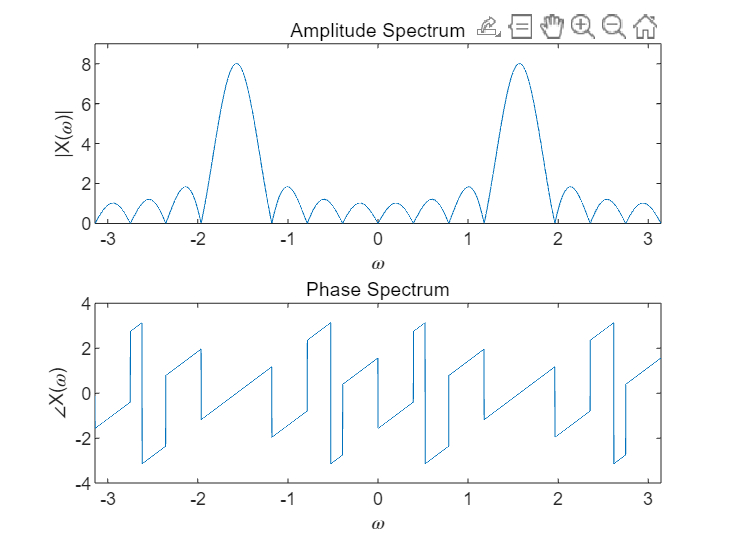

% 12번
clear
n = -10:5;
omega = -pi:1/500:pi;
x_n = cos(3*pi*n/2);
X_f = x_n*(exp(-1j*n'*omega));
X_spec = abs(X_f);
X_phase = angle(X_f);
subplot(211);
plot(omega,X_spec);
axis([-pi pi 0 9]);
xlabel('\omega');
ylabel('|X(\omega)|');
title('Amplitude Spectrum');
subplot(212);
plot(omega, X_phase);
axis([-pi pi -4 4]);
xlabel('\omega');
ylabel('\angleX(\omega)');
title('Phase Spectrum')